clear;clc;

origState = rng(17);
msg = randi([0 1],800,1);
%Generate complex signals
cfg4a = lrwpanHRPConfig( ...
    Mode='802.15.4a', ...
    MeanPRF=15.6, ...
    Channel=3, ...
    CodeIndex=6, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfg4a =   lrwpanHRPConfig with properties:

             Channel: 3
                Mode: '802.15.4a'
             MeanPRF: 15.6000
            DataRate: 0.8500
     SamplesPerPulse: 4
           CodeIndex: 6
     PreambleMeanPRF: 16.1000
    PreambleDuration: 64
             Ranging: 0
          PSDULength: 100

   Read-only properties:
          SampleRate: 1.9968e+09


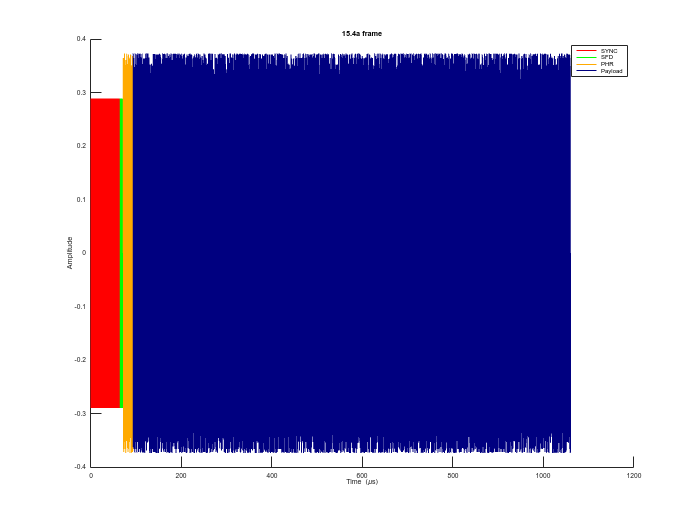

wave4a = lrwpanWaveformGenerator(msg,cfg4a);
%Note: It is a baseband signal.
lrwpanPlotFrame(wave4a,cfg4a);

%HPRF has configuration of samplesPerPulse

info(cfg4a ...
    )

ans = struct with fields:
                    PeakPRF: 499.2000
            BurstsPerSymbol: 32
               NumHopBursts: 8
              ChipsPerBurst: 16
             ChipsPerSymbol: 512
        ConvolutionalCoding: 1
         PreambleCodeLength: 31
    PreambleSpreadingFactor: 16



indices = lrwpanHRPFieldIndices(cfg4a); % length (start/end) of each field
preamble = wave4a( ...
    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)


%这是调制后的载波
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


% 旋转函数
function rotated_points = rotate_points(points, angle, center)
    theta = deg2rad(angle);
    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated_points = (rotation_matrix * (points' - center') + center')';
end

function [peaksChosen,peaksChosenValue]=findMPC(cir)
    [peaksValue,peaksIdx]=findpeaks(cir);
    %设置阈值
    threshold=0.4*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold);
    peaksChosenValue=peaksValue(peaksValue>threshold);
end


function cross_corr=CalculateXCorr(preamble,signal)
    % 计算信号的长度
    len1 = length(preamble);
    len2 = length(signal);
    
    % 扩展信号1和信号2，使其长度相等
    maxLen = max(len1, len2);
    signal1 = [preamble; zeros(maxLen - len1,1)];
    signal2 = [signal; zeros(maxLen - len2,1)];
    
    % 对信号1取复共轭
    signal1=flipud(signal1);
    signal2_conj = conj(signal2);
    
    % 计算互相关操作
    cross_corr = ifft(fft(signal2_conj) .* fft(signal1));
end


function adjusted_array = adjust_to_range(array)
    adjusted_array = array;
    for i = 1:numel(array)
        while adjusted_array(i) > pi
            adjusted_array(i) = adjusted_array(i) - 2*pi;
        end
        while adjusted_array(i) < -pi
            adjusted_array(i) = adjusted_array(i) + 2*pi;
        end
    end
end


%peaksPhase为某个TX发射，NRX个接收天线接收的相位
function AOA=CalculateAOA(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    tx_matrices = cell(1, tx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        % 提取当前子矩阵并存储到 cell 数组中
        tx_matrices{i} = peaksPhase(i:tx_array_length:length(peaksPhase),:);
    end
    AOA=[];
    for i=1:tx_array_length            
            peaksPhases=angle(tx_matrices{i});
            phaseDifferences=diff(peaksPhases);
            phaseDifferences=adjust_to_range(phaseDifferences);
            phaseSum=sum(phaseDifferences,1);
            % 计算相位差对应的到达角度（以弧度为单位）
            c=physconst('Lightspeed');
            theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
            theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
            % 将弧度转换为度数
            theta_degrees = rad2deg(theta_radians);
            theta_degrees2 = rad2deg(theta_radians2);
            theta_degrees=[theta_degrees;theta_degrees2];
            AOA=[AOA;mean(theta_degrees)];
    end
end



%peaksPhase为NTX发射，某一接收天线收到的NTX个相位
function AOD=CalculateAOD(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    rx_matrices = cell(1, rx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        start_row = (i - 1) * rx_array_length + 1;
        end_row = i * rx_array_length;
        % 提取当前子矩阵并存储到 cell 数组中
        rx_matrices{i} = peaksPhase(start_row:end_row, :);
    end
    AOD=[];
    for i = 1:rx_array_length
        peaksPhases=angle(rx_matrices{i});
        phaseDifferences=diff(peaksPhases);
        phaseDifferences=adjust_to_range(phaseDifferences);
        phaseSum=sum(phaseDifferences,1);
        % 计算相位差对应的到达角度（以弧度为单位）
        c=physconst('Lightspeed');
        theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
        theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
        % 将弧度转换为度数
        theta_degrees = rad2deg(theta_radians);
        theta_degrees2 = rad2deg(theta_radians2);
        theta_degrees=[theta_degrees;theta_degrees2];
        AOD=[AOD;mean(theta_degrees)];
    end
end


function x0 = findLocalization(theta1, theta2, phi1, phi2, rTOF)
    theta1 = deg2rad(theta1);
    theta2 = deg2rad(theta2);
    phi1 = deg2rad(phi1);
    phi2 = deg2rad(phi2);

    % 定义网格大小和范围
    gridRange = 20;
    gridSize = 0.5;

    % 生成网格点坐标
    [x1, y1, x2, y2] = ndgrid(-gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange);
    x0 = [x1(:), y1(:), x2(:), y2(:)];

    % 计算目标函数值
    objectiveValues = objectiveFunction(x0, theta1, theta2, phi1, phi2, rTOF);

    % 找到最小值
    [~, idx] = min(objectiveValues);
    x0 = x0(idx, :);
end

function fval = objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF)
    x1 = x(:, 1);
    y1 = x(:, 2);
    x2 = x(:, 3);
    y2 = x(:, 4);

    % 计算目标函数值
    fval = (tan(theta1) - x1./y1).^2 + (tan(theta2) - x2./y2).^2 + (tan(phi1 + theta1 - phi2) - (x1 - x2)./(y1 - y2)).^2 + ((rTOF * physconst('Lightspeed') * 1e-9) - (-sqrt(x1.^2 + y1.^2) + sqrt(x2.^2 + y2.^2) + sqrt((x1 - x2).^2 + (y1 - y2).^2))).^2;
end

function xOpt = optimizeLocalization(x0,theta1, theta2, phi1, phi2, rTOF)
    % 转换角度为弧度
    theta1 = deg2rad(theta1);
    theta2 = deg2rad(theta2);
    phi1 = deg2rad(phi1);
    phi2 = deg2rad(phi2);


    % 以找到的位置为中心，定义更精细的网格范围和步长
    fineRange = 1; % 细化范围为2个单位
    fineStep = 0.03; % 细化步长为0.1

    % -1:0.03:1
    % 生成更精细的网格点坐标
    [x1, y1, x2, y2] = ndgrid(x0(1)-fineRange:fineStep:x0(1)+fineRange, ...
                              x0(2)-fineRange:fineStep:x0(2)+fineRange, ...
                              x0(3)-fineRange:fineStep:x0(3)+fineRange, ...
                              x0(4)-fineRange:fineStep:x0(4)+fineRange);
    fineGrid = [x1(:), y1(:), x2(:), y2(:)];

    % 计算目标函数值
    fineObjectiveValues = objectiveFunction(fineGrid, theta1, theta2, phi1, phi2, rTOF);

    % 找到最小值
    [~, fineIdx] = min(fineObjectiveValues);
    xOpt = fineGrid(fineIdx, :);
end



function matched_peaks = matchCIRPeaks(cir_data, threshold, intensity_weight, position_weight)
    % cir_data: 数组，每个元素包含CIR数据
    % threshold: 检测峰值的阈值
    % peak_distance_tolerance: 峰位置匹配的容忍度
    % intensity_weight: 峰值强度权重
    % position_weight: 峰位置权重

    num_cir = size(cir_data,1);
    peaks_info = cell(num_cir, 1);
    % Step 1: 通过findpeaks找到每组CIR的峰值
    for i = 1:num_cir
        thre=threshold*max(abs(cir_data(i,:)));
        [peaks_first, locs_first] = findpeaks(abs(cir_data(i,:)));
      % 检查峰值数组和阈值比较
        valid_idx = peaks_first > thre;
        peaks = peaks_first(valid_idx);
        locs = locs_first(valid_idx);
        peaks_info{i}.peaks = peaks;
        peaks_info{i}.locs = locs;
    end
    
    % Step 2: 选择参考CIR
    std_devs = cellfun(@(x) std(x.peaks), peaks_info);
    total_intensities = cellfun(@(x) sum(x.peaks), peaks_info);
    
    % 标准化
    std_devs = (std_devs - min(std_devs)) / (max(std_devs) - min(std_devs));
    total_intensities = (total_intensities - min(total_intensities)) / (max(total_intensities) - min(total_intensities));
    
    % 计算综合评分
    scores = std_devs + total_intensities;
    [~, ref_idx] = min(scores); % 分数最低的作为参考CIR
    
    ref_peaks = peaks_info{ref_idx}.peaks;
    ref_locs = peaks_info{ref_idx}.locs;
    
    matched_peaks = cell(num_cir, 1);
    
    % Step 3: 匹配峰值
    for i = 1:num_cir
        if i == ref_idx
            matched_peaks{i}.peaks = ref_peaks;
            matched_peaks{i}.locs = ref_locs;
            continue;
        end
        
        curr_peaks = peaks_info{i}.peaks;
        curr_locs = peaks_info{i}.locs;
        num_ref_peaks = length(ref_peaks);
        num_curr_peaks = length(curr_peaks);
        
        % Cost matrix for matching
        cost_matrix = zeros(num_ref_peaks, num_curr_peaks);
        for j = 1:num_ref_peaks
            for k = 1:num_curr_peaks
                intensity_diff = abs(ref_peaks(j) - curr_peaks(k));
                position_diff = abs(ref_locs(j) - curr_locs(k));
                cost_matrix(j, k) = intensity_weight * intensity_diff + position_weight * position_diff;
            end
        end
        
        % Hungarian algorithm for optimal matching
        % display(cost_matrix);
        [assignment,cost] = munkres(cost_matrix);
        % display(assignment);
        % % Filter assignments with position tolerance
        [~,valid_assignments] = find(assignment);
        matched_curr_locs = curr_locs(valid_assignments);
        matched_curr_peaks = curr_peaks(valid_assignments);

        % % Check position tolerance
        % valid_idx = abs(matched_ref_locs - matched_curr_locs) <= peak_distance_tolerance;
        % matched_peaks{i}.peaks = matched_curr_peaks(valid_idx);
        % matched_peaks{i}.locs = matched_curr_locs(valid_idx);
        matched_peaks{i}.peaks = matched_curr_peaks;
        matched_peaks{i}.locs = matched_curr_locs;
    end
end

% 定义接收位置和对应的测量误差
errors=[];
TXs=[];
reflection_position=[];
tag_orientation=[];
% 定义墙面特性
wall1_position = [5, 0]; % 墙面1位置
wall2_position = [0, 5]; % 墙面2位置
reflection_coefficient = 0.8; % 反射系数

% 定义天线特性
tx_antenna_gain = 2; % 发射天线增益为 2 dB
rx_antenna_gain = 2; % 接收天线增益为 2 dB

% 配置天线阵列
tx_array_length = 3;
rx_array_length = 3;
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
tx_array_spacing = antennaSpacing;
rx_array_spacing = antennaSpacing;
tx_array_angle = 135; % 发射端天线阵列与水平轴夹角
rx_array_angle = 135; % 接收端天线阵列与水平轴夹角

% 定义天线位置
rx_position = [0, 0]; 

%UWB的频率和采样率
frequency=4992.8e6;
fs=cfg4a.SampleRate;
peaksInterval=24;

%遍历tag的位置
% tx_position = [15, 15]; 

for x=8:15
    for y=8:15
        tx_position=[x,y];
        rx_position=[0,0];
        % 计算天线阵列位置
        tx_array_positions = [tx_position-[tx_array_spacing,0];tx_position;tx_position+[tx_array_spacing,0]];
        rx_array_positions = [rx_position-[rx_array_spacing,0];rx_position;rx_position+[rx_array_spacing,0]];
        
        
        % 将天线阵列位置进行旋转
        tx_array_positions = rotate_points(tx_array_positions, tx_array_angle, tx_position);
        rx_array_positions = rotate_points(rx_array_positions, rx_array_angle, rx_position);
        

        
        % % 计算锚点到标签的向量
        % vecAnchorToTag = rx_position-tx_position;
        % 
        % 
        % 
        % 
        % % 计算锚点到标签的向量
        % vecAnchorToTag = rx_position - tx_position;
        % 
        % % 计算向量的长度
        % distAnchorToTag = norm(vecAnchorToTag);
        % 
        % % 计算向量与参考向量[-1/sqrt(2), -1/sqrt(2)]的夹角（以弧度为单位）
        % angleAnchorToTag = acos(dot(vecAnchorToTag, [-1/sqrt(2), -1/sqrt(2)]) / distAnchorToTag);
        % 
        % % 计算参考向量的叉乘以确定角度的正负值
        % cross_product = cross([-1/sqrt(2), -1/sqrt(2), 0], [vecAnchorToTag, 0]);
        
        % 如果参考向量在向量[-1/sqrt(2), -1/sqrt(2)]的上方，则夹角为负值，否则为正值
        % if cross_product(3) < 0
        %     angleAnchorToTag = -angleAnchorToTag;
        % end
        % 
        % % 将夹角转换为度数
        % angleAnchorToTag = rad2deg(angleAnchorToTag);        
        peaksPhase=[];
        timestamp=[];        
        cir_data=[];
        for j=1:rx_array_length
            rx_position = rx_array_positions(j,:);
            for i=1:tx_array_length
                tx_position = tx_array_positions(i,:);
                direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
                reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
                reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离
        
                % % 接收信号与发射信号的幅度比
                received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
                received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
                received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);
        
                % % % 接收信号与发射信号的幅度比
                % received_signal_direct=wave4a;
                % received_signal_reflection1=wave4a;
                % received_signal_reflection2=wave4a;
                
        
                % % % 设置更高的采样频率
                % fs = 5 * cfg4a.SampleRate; 
                % % % 得到各个path的多经时延信号，并进行upsampling
                % received_signal_direct = resample(received_signal_direct, fs, cfg4a.SampleRate);
                % received_signal_reflection1 = resample(received_signal_reflection1, fs, cfg4a.SampleRate);
                % received_signal_reflection2 = resample(received_signal_reflection2, fs, cfg4a.SampleRate);
                % % preamble=resample(preamble,fs,cfg4a.SampleRate);
        
                % 定义传播速度（假设与光速相同）
                speed_of_light = physconst("Lightspeed");
        
                % 计算传播时延
                direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
                reflection1_delay = reflection1_distance / speed_of_light;% 反射路径1时延（秒）
                reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）
        
        
        
                %得到各个path的多经时延信号
                received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct];
                received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs)+peaksInterval,1) ;received_signal_reflection1];
                received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs)+2*peaksInterval,1); received_signal_reflection2];
        
                len1 = length(received_signal_direct_delayed);
                len2 = length(received_signal_reflection1_delayed);
                len3 = length(received_signal_reflection2_delayed);
                maxLen = max(len1,len2);
                maxLen =max(maxLen,len3);
                received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
                received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
                received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];
        
            
                % Calculate the phase shift for each path
                direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
                reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
                reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);
        
                % Apply phase shifts to received signals
                received_signal_direct_phase = received_signal_direct_delayed .* direct_path_phase_shift;
                received_signal_reflection1_phase = received_signal_reflection1_delayed .* reflection1_phase_shift;
                received_signal_reflection2_phase = received_signal_reflection2_delayed .* reflection2_phase_shift;
        
            
                % 组合多径时延后的信号
                received_signal_total = received_signal_direct_phase + ...
                    received_signal_reflection1_phase + received_signal_reflection2_phase;
                  % received_signal_total = received_signal_direct_delayed + ...
                  %   received_signal_reflection1_delayed + received_signal_reflection2_delayed;
                
                % 
                % 添加噪声
                noise_power = -80; % 噪声功率为 -80 dBm
                noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
                
                %最终信号
                received_signal = received_signal_total + noise;
                % direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
                % reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
                % reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离
                % 
                % received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
                % received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
                % received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);
                % 
                % % 定义传播速度（假设与光速相同）
                % speed_of_light = physconst("Lightspeed");
                % 
                % % % 模拟传播过程
                % % received_signal_direct = wave4a - direct_path_loss + tx_antenna_gain + rx_antenna_gain; % 直射路径
                % % received_signal_reflection1 = wave4a * reflection_coefficient - reflection1_loss + tx_antenna_gain + rx_antenna_gain; % 墙面1反射路径
                % % received_signal_reflection2 = wave4a* reflection_coefficient - reflection2_loss + tx_antenna_gain + rx_antenna_gain; % 墙面2反射路径
                % 
                % % % % 设置更高的采样频率
                % % fs = 10 * cfg4a.SampleRate; 
                % % % % 得到各个path的多经时延信号，并进行upsampling
                % % received_signal_direct = resample(received_signal_direct, fs, cfg4a.SampleRate);
                % % received_signal_reflection1 = resample(received_signal_reflection1, fs, cfg4a.SampleRate);
                % % received_signal_reflection2 = resample(received_signal_reflection2, fs, cfg4a.SampleRate);
                % % preamble=resample(preamble,fs,cfg4a.SampleRate);
                % 
                % % Calculate the phase shift for each path
                % direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
                % reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
                % reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);
                % 
                % % Apply phase shifts to received signals
                % received_signal_direct_phase = received_signal_direct .* direct_path_phase_shift;
                % received_signal_reflection1_phase = received_signal_reflection1 .* reflection1_phase_shift;
                % received_signal_reflection2_phase = received_signal_reflection2 .* reflection2_phase_shift;
                % 
                % % 计算传播时延
                % direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
                % reflection1_delay = reflection1_distance / speed_of_light; % 反射路径1时延（秒）
                % reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）
                % 
                % %得到各个path的多经时延信号
                % received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct_phase];
                % received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs)+peaksInterval,1) ;received_signal_reflection1_phase];
                % received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs),1)+2*peaksInterval; received_signal_reflection2_phase];
                % 
                % len1 = length(received_signal_direct_delayed);
                % len2 = length(received_signal_reflection1_delayed);
                % len3 = length(received_signal_reflection2_delayed);
                % maxLen = max(len1,len2);
                % maxLen =max(maxLen,len3);
                % received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
                % received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
                % received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];
                % 
                % 
                % % 组合多径时延后的信号
                % received_signal_total = received_signal_direct_delayed + ...
                %     received_signal_reflection1_delayed + received_signal_reflection2_delayed;
                % 
                % % 添加噪声
                % noise_power = -80; % 噪声功率为 -80 dBm
                % noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
                % 
                % %最终信号
                % received_signal = received_signal_total+noise;
                receivedCorrelation=CalculateXCorr(preamble,received_signal);
                reshaped_correlation = reshape(receivedCorrelation(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
                % 对每列求平均
                average_correlation = mean(reshaped_correlation, 2);
                abs_correlation=abs(average_correlation);
                % plot(average_correlation);
                % cir_data=[cir_data;receivedCorrelation(1:length(preamble))'];     
                [peaksChosen,peaksChosenValue]=findMPC(abs_correlation);
                phases=receivedCorrelation(peaksChosen);
                peaksPhase=[peaksPhase;phases(1:end)'];
                timestamp=[timestamp;[peaksChosen(1),peaksChosen(2)-peaksInterval,peaksChosen(3)-2*peaksInterval]*1e9 / fs];

            end
        end

        % matched_peaks=matchCIRPeaks(cir_data,0.3,0.5,0.5);
        % for i = 1:tx_array_length*rx_array_length
        %     cir=cir_data(i,:);
        %     fprintf('CIR %d:\n', i);
        %     disp('Matched Peaks:');
        %     disp(matched_peaks{i}.peaks);
        %     disp('Matched Locations:');
        %     disp(matched_peaks{i}.locs);
        %     peakChosen=matched_peaks{i}.locs;
        %     peaksPhase=[peaksPhase;cir(peakChosen)];
        %     timestamp=[timestamp;matched_peaks{i}.locs*1e9 / fs];
        % end
        % if size(peaksPhase,2)>1
        %     AOD=mean(CalculateAOD(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
        %     AOA=mean(CalculateAOA(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
        %     timestamp=mean(timestamp,1);
        %     rTOF=timestamp-timestamp(1);
        %     rDistance=rTOF*physconst('Lightspeed')*1e-9;
        %     x0=findLocalization(AOA(1),AOA(2),AOD(1),AOD(2),rTOF(2));
        %     % 顺时针旋转45°的旋转矩阵
        %     x0=reshape(x0,2,2);
        %     x0(2,:)=-x0(2,:);
        %     theta = deg2rad(45);
        %     R = [cos(theta), sin(theta); -sin(theta), cos(theta)];        
        %     % 旋转后的向量
        %     result = R * x0(:,1);
        % else 
        %     result=[inf,inf];
        % end
            % 显示结果
        AOD=mean(CalculateAOD(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
        AOA=mean(CalculateAOA(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
        timestamp=mean(timestamp,1);
        rTOF=timestamp-timestamp(1);
        rDistance=rTOF*physconst('Lightspeed')*1e-9;    
        x0=findLocalization(AOA(1),AOA(2),AOD(1),AOD(2),rTOF(2));
        x0=optimizeLocalization(x0,AOA(1),AOA(2),AOD(1),AOD(2),rTOF(2));
        % 顺时针旋转45°的旋转矩阵
        x0=reshape(x0,2,2);
        x0(2,:)=-x0(2,:);
        theta = deg2rad(45);
        R = [cos(theta), sin(theta); -sin(theta), cos(theta)];        
        % 旋转后的向量
        rotated_vector = R * x0;
        reflection_position=[reflection_position;rotated_vector(:,2)'];
        x1=findLocalization(AOA(1),AOA(3),AOD(1),AOD(3),rTOF(3));
        x1=optimizeLocalization(x1,AOA(1),AOA(3),AOD(1),AOD(3),rTOF(3));
        % 顺时针旋转45°的旋转矩阵
        x1=reshape(x1,2,2);
        x1(2,:)=-x1(2,:);
        theta = deg2rad(45);
        R = [cos(theta), sin(theta); -sin(theta), cos(theta)];
        % 旋转后的向量
        rotated_vector1 = R * x1;
        reflection_position=[reflection_position;rotated_vector1(:,2)'];
        result=(rotated_vector(:,1)+rotated_vector1(:,1))/2;
        orientation=atan(result(2)/result(1));
        orientation=-AOA(1)+rad2deg(orientation);
        tag_orientation=[tag_orientation,orientation];
        disp("TX:");
        disp([x,y])
        disp("Result:")
        disp(result);
        disp("Error:")
        error=sqrt((result(1)-x)^2+(result(2)-y)^2);
        disp(error);
        TXs=[TXs;[x,y]];
        errors=[errors;error];
        
        end 
end

TX:


     8     8



Result:


    8.0646
    8.0575



Error:


    0.0864



TX:


     8     9



Result:


    8.1742
    9.1641



Error:


    0.2393



TX:


     8    10



Result:


    8.7151
   10.7445



Error:


    1.0323



TX:


     8    11



Result:


    7.7075
   10.6349



Error:


    0.4679



TX:


     8    12



Result:


    8.3262
   12.4133



Error:


    0.5265



TX:


     8    13



Result:


    7.9196
   12.8198



Error:


    0.1973



TX:


     8    14



Result:


    8.4040
   14.6619



Error:


    0.7754



TX:


     8    15



Result:


    8.1034
   15.1674



Error:


    0.1968



TX:


     9     8



Result:


    9.1500
    8.1459



Error:


    0.2092



TX:


     9     9



Result:


    8.8919
    8.9060



Error:


    0.1433



TX:


     9    10



Result:


    9.0899
   10.0232



Error:


    0.0928



TX:


     9    11



Result:


    8.6267
   10.5571



Error:


    0.5792



TX:


     9    12



Result:


    8.8636
   11.8264



Error:


    0.2208



TX:


     9    13



Result:


    9.2065
   13.3360



Error:


    0.3944



TX:


     9    14



Result:


    8.8035
   13.6472



Error:


    0.4039



TX:


     9    15



Result:


    8.8600
   14.7856



Error:


    0.2560



TX:


    10     8



Result:


   10.7728
    8.7504



Error:


    1.0772



TX:


    10     9



Result:


   10.0621
    9.1358



Error:


    0.1494



TX:


    10    10



Result:


   10.3132
   10.3273



Error:


    0.4530



TX:


    10    11



Result:


   10.1116
   11.1228



Error:


    0.1659



TX:


    10    12



Result:


   10.5889
   12.5405



Error:


    0.7994



TX:


    10    13



Result:


   10.2530
   13.3219



Error:


    0.4094



TX:


    10    14



Result:


    9.6838
   13.5446



Error:


    0.5544



TX:


    10    15



Result:


    9.9349
   14.8775



Error:


    0.1387



TX:


    11     8



Result:


   10.6101
    7.7110



Error:


    0.4853



TX:


    11     9



Result:


   10.5748
    8.6727



Error:


    0.5366



TX:


    11    10



Result:


   11.0768
   10.0727



Error:


    0.1058



TX:


    11    11



Result:


   10.8435
   10.8788



Error:


    0.1979



TX:


    11    12



Result:


   11.3773
   12.4239



Error:


    0.5675



TX:


    11    13



Result:


   11.5152
   13.6295



Error:


    0.8135



TX:


    11    14



Result:


   11.4162
   14.4214



Error:


    0.5923



TX:


    11    15



Result:


   10.6561
   14.5735



Error:


    0.5479



TX:


    12     8



Result:


   12.4203
    8.3191



Error:


    0.5277



TX:


    12     9



Result:


   11.7910
    8.8353



Error:


    0.2661



TX:


    12    10



Result:


   12.5900
   10.5606



Error:


    0.8139



TX:


    12    11



Result:


   12.4628
   11.4233



Error:


    0.6272



TX:


    12    12



Result:


   12.7244
   12.7597



Error:


    1.0497



TX:


    12    13



Result:


   11.5789
   12.6254



Error:


    0.5636



TX:


    12    14



Result:


   11.8228
   13.7462



Error:


    0.3096



TX:


    12    15



Result:


   11.7733
   14.7007



Error:


    0.3754



TX:


    13     8



Result:


   12.8163
    7.9019



Error:


    0.2082



TX:


    13     9



Result:


   13.3643
    9.2207



Error:


    0.4259



TX:


    13    10



Result:


   13.2335
   10.1929



Error:


    0.3029



TX:


    13    11



Result:


   13.5411
   11.4763



Error:


    0.7209



TX:


    13    12



Result:


   12.6537
   11.6567



Error:


    0.4877



TX:


    13    13



Result:


   13.5552
   13.5270



Error:


    0.7655



TX:


    13    14



Result:


   13.0638
   14.0962



Error:


    0.1154



TX:


    13    15



Result:


   13.2441
   15.3230



Error:


    0.4049



TX:


    14     8



Result:


   14.4957
    8.2944



Error:


    0.5765



TX:


    14     9



Result:


   13.6224
    8.7434



Error:


    0.4565



TX:


    14    10



Result:


   13.5517
    9.6980



Error:


    0.5405



TX:


    14    11



Result:


   14.4073
   11.4516



Error:


    0.6081



TX:


    14    12



Result:


   13.7850
   11.8051



Error:


    0.2901



TX:


    14    13



Result:


   14.1351
   13.0885



Error:


    0.1615



TX:


    14    14



Result:


   13.7391
   13.7108



Error:


    0.3895



TX:


    14    15



Result:


   13.2936
   14.2836



Error:


    1.0061



TX:


    15     8



Result:


   15.4185
    8.2130



Error:


    0.4696



TX:


    15     9



Result:


   14.7609
    8.8424



Error:


    0.2864



TX:


    15    10



Result:


   14.9695
    9.9490



Error:


    0.0595



TX:


    15    11



Result:


   14.5805
   10.7127



Error:


    0.5084



TX:


    15    12



Result:


   14.7396
   11.7557



Error:


    0.3571



TX:


    15    13



Result:


   15.3407
   13.3325



Error:


    0.4760



TX:


    15    14



Result:


   14.3118
   13.2653



Error:


    1.0066



TX:


    15    15



Result:


   14.5098
   14.4815



Error:


    0.7135



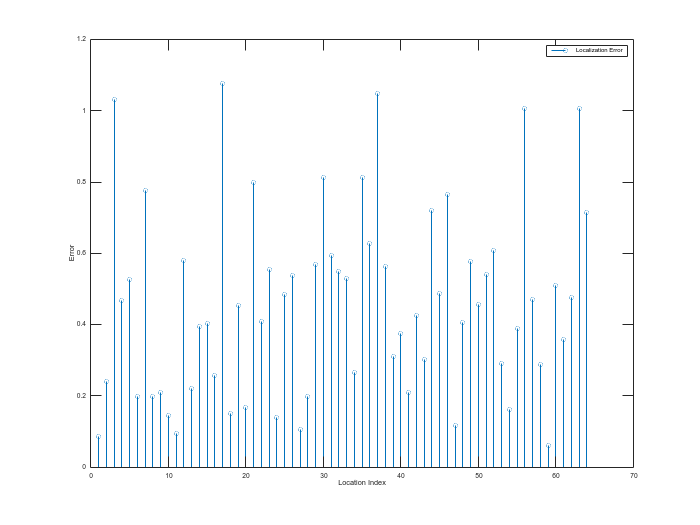

% figure;
% plot([errors,mean(errors,2)]);
% xlabel('Location Index');
% ylabel('Error');
% legend("AOD Error 1","AOD Error 2","AOD Error 3","Mean AOD Error");

figure;
stem(errors);
xlabel('Location Index');
ylabel('Error');
legend("Localization Error");

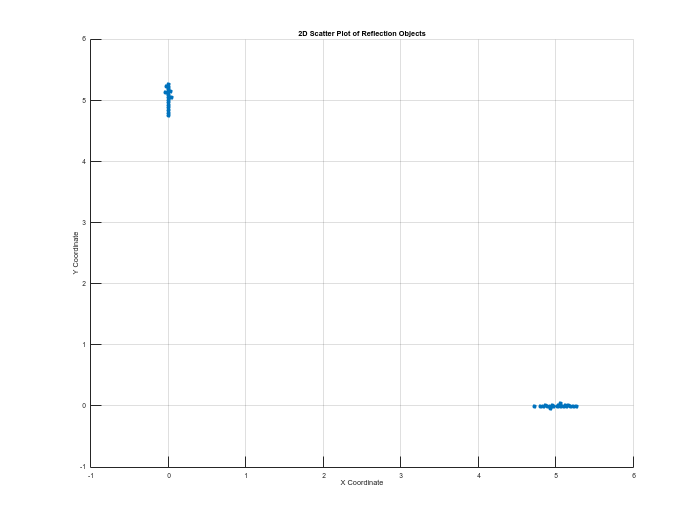

% 提取 x 和 y 坐标
reflection_x = reflection_position(:, 1);
reflection_y = reflection_position(:, 2);

% 在二维平面上绘制这些点
figure;
scatter(reflection_x, reflection_y, 'filled'); % 使用散点图表示
title('2D Scatter Plot of Reflection Objects');
xlabel('X Coordinate');
ylabel('Y Coordinate');
grid on; % 添加网格以便更好地观察

orientation=mean(tag_orientation)

orientation = 44.9984